# Problema 3

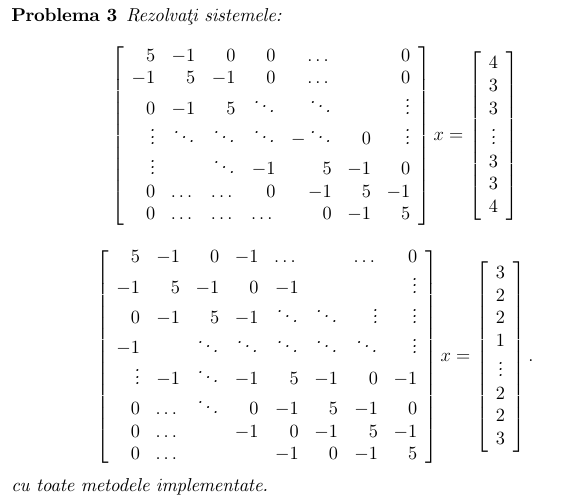

## Generarea matricilor

function [M, d] = construieste_sistem1(n)
    diag_princ = 5 * ones(n,1);
    diag_vecini = -1 * ones(n-1,1);

    M = diag(diag_princ) + diag(diag_vecini,1) + diag(diag_vecini,-1);

    d = 3 * ones(n,1);
    d([1 end]) = 4;
end

function [M, d] = construieste_sistem2(n)
    if round(sqrt(n))^2 ~= n
        error('n trebuie să fie pătrat perfect pentru această structură.');
    end

    diag_centrala = 5 * ones(n,1);
    diag_adiacenta = -1 * ones(n-1,1);

    M = diag(diag_centrala) + diag(diag_adiacenta,1) + diag(diag_adiacenta,-1);

    offset = sqrt(n);
    for i = 1:n
        if i + offset <= n
            M(i, i+offset) = -1;
            M(i+offset, i) = -1;
        end
    end

    d = 2 * ones(n,1);
    d([1 end]) = 3;
    if n >= 4
        d(4) = 1;
    end
end


[A1, b1] = construieste_sistem1(10)

A1 =      5    -1     0     0     0     0     0     0     0     0
    -1     5    -1     0     0     0     0     0     0     0
     0    -1     5    -1     0     0     0     0     0     0
     0     0    -1     5    -1     0     0     0     0     0
     0     0     0    -1     5    -1     0     0     0     0
     0     0     0     0    -1     5    -1     0     0     0
     0     0     0     0     0    -1     5    -1     0     0
     0     0     0     0     0     0    -1     5    -1     0
     0     0     0     0     0     0     0    -1     5    -1
     0     0     0     0     0     0     0     0    -1     5


b1 =      4
     3
     3
     3
     3
     3
     3
     3
     3
     4


[A2, b2] = construieste_sistem2(9) 

A2 =      5    -1     0    -1     0     0     0     0     0
    -1     5    -1     0    -1     0     0     0     0
     0    -1     5    -1     0    -1     0     0     0
    -1     0    -1     5    -1     0    -1     0     0
     0    -1     0    -1     5    -1     0    -1     0
     0     0    -1     0    -1     5    -1     0    -1
     0     0     0    -1     0    -1     5    -1     0
     0     0     0     0    -1     0    -1     5    -1
     0     0     0     0     0    -1     0    -1     5


b2 =      3
     2
     2
     1
     2
     2
     2
     2
     3


## Metoda Jacobi

%PB 1
function [aprox, num_iteratii] = metoda_jacobi(A, b, tol, iter_max)
    n = size(A, 1);                 
    x_vechi = zeros(n, 1);           
    aprox = zeros(n, 1);             
    num_iteratii = 0;                

    while num_iteratii < iter_max
        for i = 1:n
            suma = 0;
            for j = 1:n
                if j ~= i
                    suma = suma + A(i,j) * x_vechi(j);
                end
            end
            aprox(i) = (b(i) - suma) / A(i,i);
        end
        if norm(aprox - x_vechi, inf) < tol
            break;
        end
        x_vechi = aprox;
        num_iteratii = num_iteratii + 1;
    end
end

## Metoda SOR + Gauss-Seidel

%PB2
function [solutie, nr_iteratii] = metoda_sor(A, b, w, tol, iter_max)
    n = length(b);
    x = zeros(n, 1);             
    nr_iteratii = 0;

    while nr_iteratii < iter_max
        x_vechi = x;             

        for i = 1:n
            s = A(i,:) * x - A(i,i) * x(i);   

            x(i) = (1 - w) * x_vechi(i) + w * (b(i) - s) / A(i,i);
        end

        nr_iteratii = nr_iteratii + 1;
        if norm(x - x_vechi, inf) < tol
            break;
        end
    end

    solutie = x;
end
function w_opt = calculeaza_omega_opt(A)
    D = diag(diag(A));
    L = tril(A, -1);
    U = triu(A, 1);

    T = -inv(D) * (L + U);
    p = max(abs(eig(T)));

    if p >= 1
        warning("Jacobi nu converge, ω optim nu poate fi estimat.");
        w_opt = NaN;
    else
        w_opt = 2 / (1 + sqrt(1 - p^2));
    end
end

## Functia de verificare 

function verifica_rezultat(M, d, sol)
    if norm(M*sol - d, inf) < 1e-6
        disp('Soluția este corectă.');
    else
        disp('Soluția NU este corectă.');
    end
end

epsilon = eps(1);
max_iter = 10000;

## Rezolvarea sist 1

[x, iter] = metoda_jacobi(A1, b1, epsilon, max_iter);
fprintf('Metoda Jacobi\nSoluția aproximată:\n');

Metoda Jacobi
Soluția aproximată:


disp(x');

     1     1     1     1     1     1     1     1     1     1



fprintf('Număr de iterații: %d\n', iter);

Număr de iterații: 39


verifica_rezultat(A1,b1,x);

Soluția este corectă.



omega = 1;
[x, iter] = metoda_sor(A1, b1, omega, epsilon, max_iter);
fprintf('Metoda Gauss-Seidel\nSoluția aproximată:\n');

Metoda Gauss-Seidel
Soluția aproximată:


disp(x');

     1     1     1     1     1     1     1     1     1     1



fprintf('Număr de iterații: %d\n', iter);

Număr de iterații: 24


verifica_rezultat(A1,b1,x);

Soluția este corectă.



omega = calculeaza_omega_opt(A1);
[x, iter] = metoda_sor(A1, b1, omega, epsilon, max_iter);
fprintf('Metoda SOR\nSoluția aproximată:\n');

Metoda SOR
Soluția aproximată:


disp(x');

     1     1     1     1     1     1     1     1     1     1



fprintf('Număr de iterații: %d\n', iter);

Număr de iterații: 17


verifica_rezultat(A1,b1,x);

Soluția este corectă.


fprintf('===========================================');

## Rezolvarea sist 2

[x, iter] = metoda_jacobi(A2, b2, epsilon, max_iter);
fprintf('Metoda Jacobi\nSoluția aproximată:\n');

Metoda Jacobi
Soluția aproximată:


disp(x');

    1.0428    1.0960    1.1082    1.1180    1.3292    1.3267    1.1100    1.1051    1.0864



fprintf('Număr de iterații: %d\n', iter);

Număr de iterații: 89


verifica_rezultat(A2,b2,x);

Soluția este corectă.



omega = 1;
[x, iter] = metoda_sor(A2, b2, omega, epsilon, max_iter);
fprintf('Metoda Gauss-Seidel\nSoluția aproximată:\n');

Metoda Gauss-Seidel
Soluția aproximată:


disp(x');

    1.0428    1.0960    1.1082    1.1180    1.3292    1.3267    1.1100    1.1051    1.0864



fprintf('Număr de iterații: %d\n', iter);

Număr de iterații: 10000


verifica_rezultat(A2,b2,x);

Soluția este corectă.



omega = calculeaza_omega_opt(A2);
[x, iter] = metoda_sor(A2, b2, omega, epsilon, max_iter);
fprintf('Metoda SOR\nSoluția aproximată:\n');

Metoda SOR
Soluția aproximată:


disp(x');

    1.0428    1.0960    1.1082    1.1180    1.3292    1.3267    1.1100    1.1051    1.0864



fprintf('Număr de iterații: %d\n', iter);

Număr de iterații: 10000


verifica_rezultat(A2,b2,x);

Soluția este corectă.
